Q-1

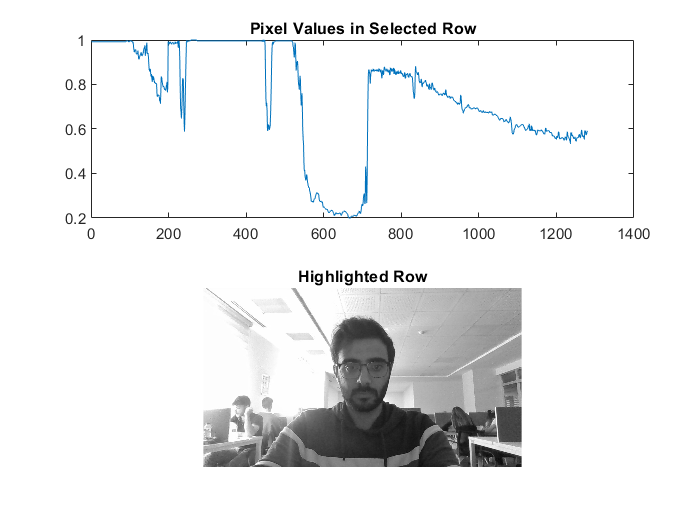

% Read the double grayscale image
ahmet = imread('ahmet.jpg');
ahmet_gray = rgb2gray(ahmet);
ahmet_double = im2double(ahmet_gray);

% Choose a row to plot
selected_row = 150; % You can change this value to the desired row

% Plot the values of the pixels in the selected row
subplot(2, 1, 1);
plot(ahmet_double(selected_row, :));
title('Pixel Values in Selected Row');

% Find the pixel with the highest brightness
[max_brightness, max_index] = max(ahmet_double(selected_row, :));

% Highlight the row with the highest brightness
highlighted_ahmet = ahmet_double;
highlighted_ahmet(selected_row, :) = 1.0; % Set the entire row to white

% Display the highlighted image
subplot(2, 1, 2);
imshow(highlighted_ahmet);
title('Highlighted Row');


% Display the pixel with the highest brightness
fprintf('The pixel with the highest brightness in row %d is at index %d.\n', selected_row, max_index);

The pixel with the highest brightness in row 150 is at index 247.


fprintf('The brightness value is: %f.\n', max_brightness);

The brightness value is: 1.000000.
